clear
clf

**Pre dimension of clamping hub with Springers**

format shortg
d_shaft_dim = [95 80 48 55 38]; % diffrent main size hubs
d_hub = 2*d_shaft_dim

**Bolt pretension**

Data

S_y = 1100; %940; %10.9 %1100  12.9; %yield strength
A_t = [245 84.3 58 20.1]; % tensile strength cross section area
d = [0.020 0.012 0.010 0.006]; % Bolt diameter metric class
p = [0.0025 0.00175 0.0015 0.001]; %  %pitch (afstand fra top til top)
A_r = [225 76.3 52.3 17.9] * (1/1000)^2; %areal fra roddiameter se table 8-1 i shigleys eller one note
d_r = sqrt(4 * A_r / pi); % root diameteren
d_m = (d + d_r)/2;      % Mean diameter
d_p = (d + d_r)/2;      % Pitch diameter
D_Km = d * 1.3          % Mean bearing diameter at the nut or at the bolt head springer side 534
d_w = [0.030 0.018 0.016 0.010]; % M20 M12 M10 M6 bolt type ISO 4762
d_h = [0.021 0.013 0.0105 0.0064];% Hole diameter
l = p; % Amount of starting leads on thread
lambda = atan(l/(pi*d_m)); %stigningsvinklen i gevind
f = 0.18; %friktionskoefficienten i gevind
fc = 0.18; %friktionskoefficienten i spændeskive
alpha = 30; %grader %30 grader er den typiske vinkel
d_c_min = [0.021 0.013 0.0105 0.0064];%0.011 %* u.mm; %mindste diameter på spændeskive
d_c_max = [0.034 0.020 0.018 0.011] %d_c_min * 1.5%0.016 %* u.mm; %største diameter på spændeskive
% d_c_min * 1.5
d_c =  (d_c_min + d_c_max) / 2; %middel diameter på spændeskive
n_bolts = [4 4 4 2]; % number of bolts


**Finding pretension according to shigleys**

S_p = 0.85 * S_y; % proff strength
F_p = S_p * A_t; % proff force
F_i = 0.75 * F_p % n_bolts% nonperm

**Resilience of the bolt**

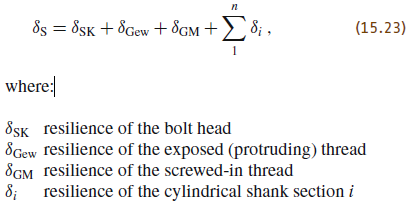

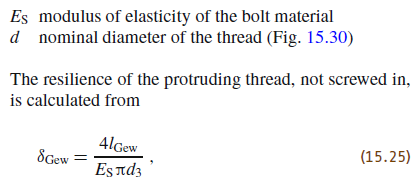

l_SK = d * 0.4; %for hexagon socket head cap screws (bolts),
E_s = 207e9;   % young modulus for the bolt for stål 207 GPa E-modul
delta_SK = 4 * l_SK/(E_s * pi * d)

l_Gew = 0.017; % length of the protruding thread (not engaged)
delta_Gew = 4 * l_Gew ./ (E_s * pi * d_r)

E_M = E_s; % young modulus for the nut/hole
l_G = 0.5 * d_r % as a rule page 529. 10mm is half.
delta_G = 4 * l_G / (E_s * pi * d_r)

l_M = 0.33 * d % as a rule page 529.
delta_M = 4 * l_M / (E_M * pi * d)

delta_GM = delta_G + delta_M

l_1 = [0.0075 0.0053 0.0045 0.003]; % full threaded
d_1 = d; % full threaded
delta_i = 4 * l_1 ./ (E_s * pi * d_1) % add one for each diameter size

delta_S = delta_SK + delta_Gew + delta_GM + delta_i %exstendtion of the bolt

**Resilience of the material**

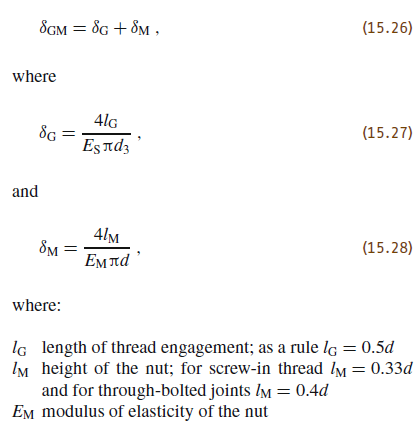

The resiliences of the individual shank areas

(15.32)

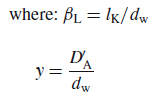

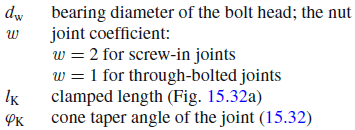

For screw in joint

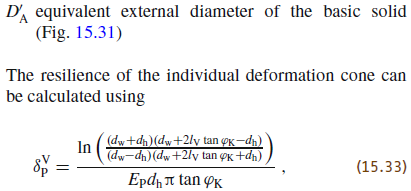

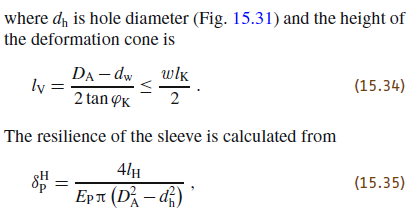

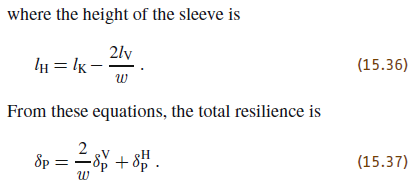

E_P = E_M
l_K = 0.026;
D_A = 0.018; % diameter ved tryk keglens max Fig. 15.31
D_A_mark = 0.018; 


beta_L = l_K ./ d_w
y = D_A_mark ./ d_w
tan_phi_KE = 0.348 + 0.013 * log(beta_L) + 0.193 * log(y)
l_V = (D_A - d_w) ./ (2*tan_phi_KE) % ligning 15.34

tan_phi_K = tan_phi_KE


delta_V_P = log( ( (d_w + d_h) .* (d_w + 2.*l_V .* tan_phi_K - d_h) ) ./...
     ( (d_w - d_h) .* (d_w + 2*l_V .* tan_phi_K + d_h) ) ) ./...
     (E_P .* d_h .* pi .* tan_phi_K) % ligning 15.33
delta_V_P = 0

l_H = 15.5 + (23+1.5)/2; %l_k - 2*l_V/w % 15.36

delta_H_P = (4 * l_H) ./ (E_P * pi .* (D_A.^2 - d_h.^2))

w = 2; % joint coeffecient; 2 for screw-in joints, 1 for through-bolted joints

delta_P = 2/w * delta_V_P + delta_H_P

f_Z = (3 + 3)*1e-6 % surface roughness 10-40

F_Z = f_Z ./ (delta_S + delta_P)

**Tightning torque needed found with springer**

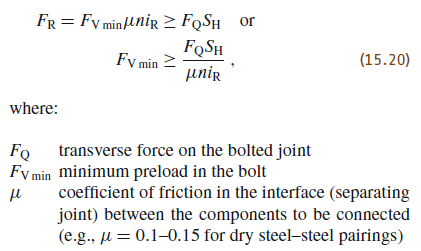

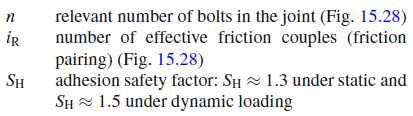

$F_A$ - additionally loaded by an axial working load 

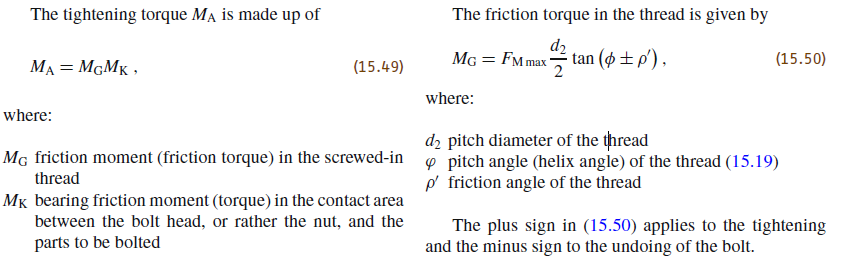

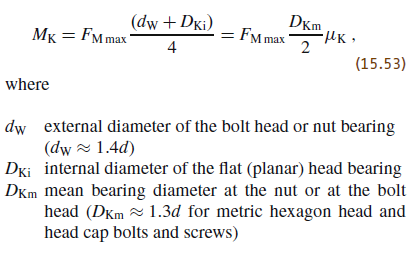

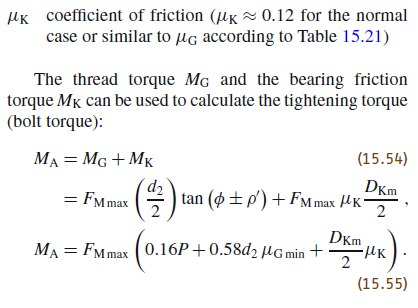

Med springer

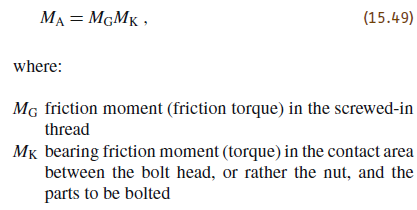

F_Z = 0; % The resulting loss of force is called the loss of preload
F_Mmin = F_i + F_Z
alpha_A = 1.6% tightening factor % Table 15.19: Tightening with torque wrench
F_Mmax = alpha_A * F_Mmin % 
mu_G_min = 0.12; % Table 15.21 dry black tempered / steel blank
mu_K = 0.12; % for the normal case or similar to mu_G according to Table 15.21
M_A = F_Mmax .* (0.16*p + 0.58*d_p * mu_G_min + D_Km/2 * mu_K)

Med shigleys

%funktion for forspændingsmomentet with shigleys (uniform pressure cone)
% T_for = (F_i .* d_m/2) * ((tan(lambda) + f * secd(alpha)) ./...
%     (1 - f * tan(lambda) * secd(alpha))) + (F_i * fc .* d_c)/2
% T_ = vpa(unitConvert(T, u.N * u.m), 4)
% T_bolt = T_for / n_bolts

d_shaft = [95e-3 55e-3 55e-3 60e-3]; %48e-3

"Is the friction higher then the max force from the"
F_i_fric = F_i * 4 * 0.2 %f
T_max = [5.1e3 1e3 1e3 100]; %473
F_max = T_max ./ (d_shaft/2)

F_i_max = F_max; %/ n_bolts;
F_i_fric > F_i_max
"max torque"
% T_max = (F_i_max .* d_m/2) * ((tan(lambda) + f * secd(alpha)) ./...
%     (1 - f * tan(lambda) * secd(alpha))) + (F_i_max * fc .* d_c)/2
" "

**a dobbelt check on how much torque the screws can take **

d_r % root diameter of bolt
tau_max = 1100e6
T_max_calc = tau_max / 16 * (pi * d_r.^3) % torque at max torsion
M_A
T_max_calc > M_A
" "

**Shear and normal stress under bolts**

F_Mmax
F_i
t = [0.034 0.022 0.022 0.010]; % thickness of material under bolts
w = d_w - d_h
% A_flade = [113e-6*4 113e-6 113e-6 113e-6]; % only taken for 1kNm small
A_flade = pi*(d_w/2).^2 - pi*(d_h/2).^2 % normal force area
sigma_m = F_Mmax ./ A_flade; %Normal stress
sigma_m_mpa = sigma_m * 1e-6 

A_cross = t .* w % cross area of material under bolt
tau_m = F_Mmax ./ A_cross; % shear stress under bolt
tau_m_mpa = tau_m * 1e-6

**Pressure on small shafts**

L = [80 80 59 39]; % engaged length
d_small = [48 48 28 14]; %shaft diameter
A = L.*d_small % shadow area of shaft
F_Mmax
F_Mmax = [274890 94585 94585 22552]%alpha_A * F_Mmin % 
sigma_shaft = F_Mmax*4 ./ A % normal stress on shaft

Material needed is AISI 1141 or AISI 1137 water quenched

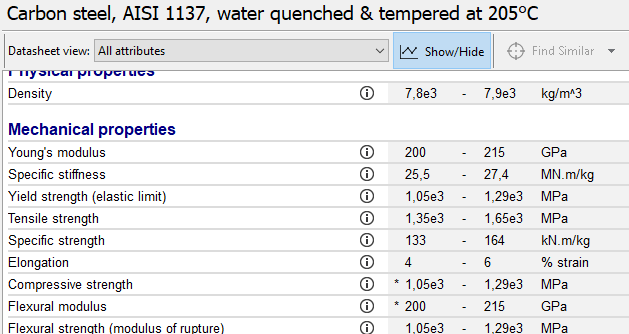

(from EduPack)

**Dynamsike krafter**

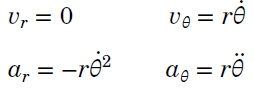

RPM = [7200 3200 1600]
omega = RPM / 60 * 2 * pi % angualr speed rad/s
%distance to center of mass

**top clamping piece**

Data is from solidworks

y = 0.023272; 
z = 0.00385;
r_center = sqrt(y^2 + z^2)
m = 1.5; %kg
a_r = r_center * omega.^2
F_clamp = m * a_r
F_clamp_bolt = F_clamp/4

**Claw piece**

y = 0.012095;
z = 0.00181;
r_center = sqrt(y^2 + z^2)
m = 3.3; %kg
a_r = r_center * omega.^2
F_claw = m * a_r
F_claw_bolt = F_claw/4

unbalance in force

F_total = F_claw - F_clamp

See that the worst case for 1kN m

is a 120 Hz, 2 pole,  FS 355 and FS 400

RPM = 7200

Torque 849

For 0.1kN m it is 120 Hz 2 pole, FS 225

RPM = 7200

Torque = 96

Surface pressure

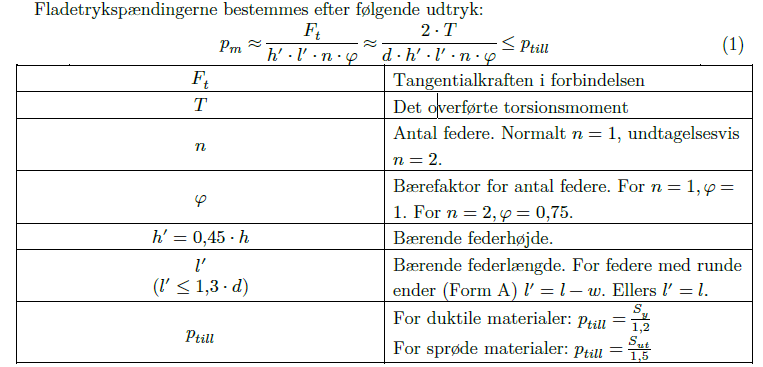

T = 1000;
d = 48e-3;
h = 9e-3;%shaft 44-50
h_mark = h * 0.45 
l = 71e-3;%160e-3;
w = 14e-3/2; % only one rounding in engangement
l_mark = l -w% form a
p_m = 2 * T / (d * h_mark * l_mark);
p_m_MPA = p_m /1e6 %fatigue stength according to EduPack C45 normalized
% steel is 274MPa til 317MPa
% Bevægelig not brede D10 Glidepasning for nav
% Edupack E295 annealed 217MPa - 255MPa 
